% %generate tf with no zeros and 10 equally spaced poles
% clear all
% Z = [];
% theta(1)=0;
% rho(1)=1;
% for i = 1:9
% theta(i+1)=(2*i*pi/10);
% rho(i+1)=1;
% end 
% K = 1;
% [x,y]=pol2cart(theta,rho)
% for i=1:length(x)
% P(i)=x(i)+y(i)*1i;
% end
% sys = zpk(Z,P,K);
% pzmap(sys)
Z=[];
K=1;
[~,P]=geteqpols(10);

%generate tf with no zeros and 5 equally spaced poles in LHP
P2=P(4:8);
sys = zpk(Z,P2,K);

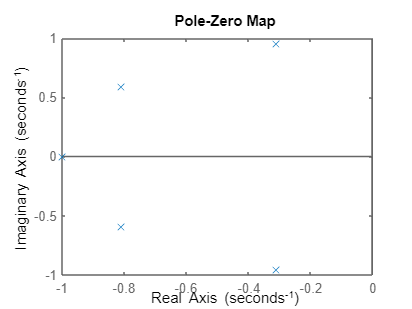

pzmap(sys)

%computing step response
stepinfo(sys)

ans = struct with fields:
         RiseTime: 2.5633 + 0.0000i
    TransientTime: 10.8386 + 0.0000i
     SettlingTime: 10.8386 + 0.0000i
      SettlingMin: 0.9090 + 0.0000i
      SettlingMax: 1.1277 + 0.0000i
        Overshoot: 0
       Undershoot: 0
             Peak: 1.1277
         PeakTime: 6.3551


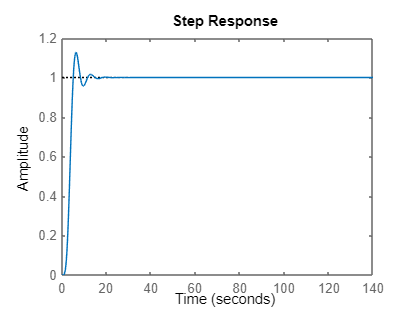

step(sys)

%repeating a) and b) for 6 & 14 poles

[~,P2]=geteqpols(6);

[~,P3]=geteqpols(14);


P2=P2(3:5);
sys2 = zpk(Z,P2,K);

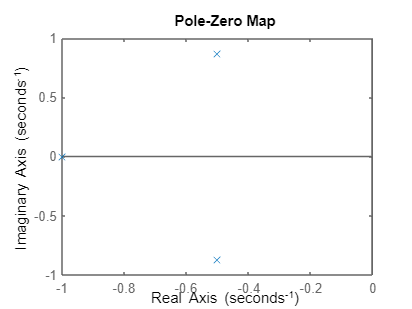

pzmap(sys2)


stepinfo(sys2)

ans = struct with fields:
         RiseTime: 2.2911 - 0.0000i
    TransientTime: 6.6376 + 0.0000i
     SettlingTime: 6.6376 + 0.0000i
      SettlingMin: 0.9050 + 0.0000i
      SettlingMax: 1.0814 + 0.0000i
        Overshoot: 0
       Undershoot: 0
             Peak: 1.0814
         PeakTime: 4.8815


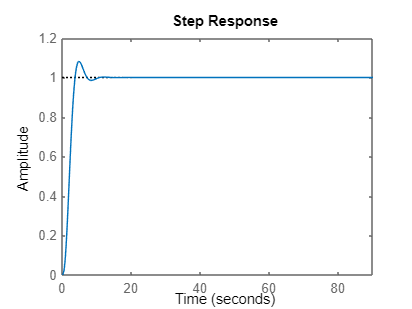

step(sys2)


P3=P3(5:11);
sys3 = zpk(Z,P3,K);

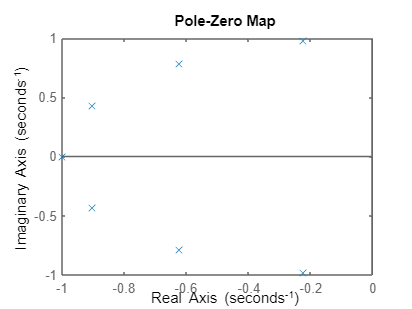

pzmap(sys3)


stepinfo(sys3)

ans = struct with fields:
         RiseTime: 2.7880 - 0.0000i
    TransientTime: 15.2063 + 0.0000i
     SettlingTime: 15.2063 + 0.0000i
      SettlingMin: 0.9046 + 0.0000i
      SettlingMax: 1.1541 + 0.0000i
        Overshoot: 0
       Undershoot: 0
             Peak: 1.1541
         PeakTime: 7.7554


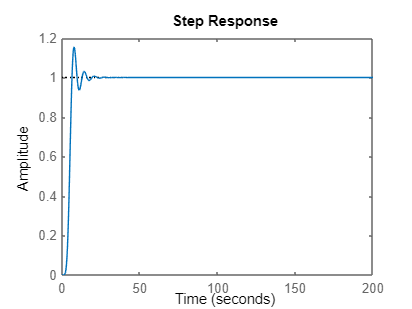

step(sys3)

function [sys,P]=geteqpols(n)
Z = [];
theta(1)=0;
rho(1)=1;
for i = 1:n-1
theta(i+1)=(2*i*pi/n);
rho(i+1)=1;
end 
K = 1;
[x,y]=pol2cart(theta,rho);
for i=1:length(x)
P(i)=x(i)+y(i)*1i;
end
sys = zpk(Z,P,K);

end
